# Ejes de coordenadas

Dificultad: Normal (Básico)

## Ejes en el espacio

- **Definición**: Un eje viene determinado por una posición en el espacio y una orientación con respeto a otro eje definido. 

- **Posición**: Coordenadas $[x,y,z]$, medido en metros o milímetros respecto a una referencia.

- **Orientación**: Existen muchas maneras de medir la orientación del eje $x$, eje $y$ y eje $z$  respecto a otro eje de referencia.

## Teorema de Euler: 

- Dos sistemas de coordenadas ortonormales independientes (ejes) pueden relacionarse por una secuencia de rotaciones (no más de tres) alrededor de ejes de coordenadas, donde no hay dos rotaciones sucesivas alrededor del mismo eje.

## Matrices de rotación básicas en $x$,$y$ y $z$

- Definen la matriz de rotación entre dos ejes con giro en los ejes $x$,$y$ o $z$.

- Rotación en $x$, $R_x(\theta)= \left[\begin{array}{ccc} 
                      1 &  0  &  0 \\
                      0 & c(\theta) &  -s(\theta) \\
                      0 & s(\theta) & c(\theta)
          \end{array}\right] $

- Rotación en $y$, $R_y(\theta)= \left[\begin{array}{ccc}
                     c(\theta) & 0 & s(\theta) \\
                       0 &    1 &     0 \\
                     -s(\theta) & 0 & c(\theta) 
          \end{array}\right]$

- Rotación en $z$, $  R_z(\theta)= \left[\begin{array}{ccc}
                      c(\theta)& -s(\theta)& 0\\
                      s(\theta)& c(\theta)& 0\\
                       0 &        0 &       1
         \end{array}\right]$

deg= pi/180;
% Función anónima de para definir matrices de rotación básicas
Rx= @(theta) [1,0,0,; 0,cos(theta),-sin(theta); 0,sin(theta),cos(theta)];
Ry= @(theta) [cos(theta),0,sin(theta); 0,1,0; -sin(theta),0,cos(theta)];
Rz= @(theta) [cos(theta),-sin(theta),0; sin(theta),cos(theta),0; 0,0,1];

Rx(30*deg)

ans =     1.0000         0         0
         0    0.8660   -0.5000
         0    0.5000    0.8660


## Matriz de rotación general           

- Matriz de rotación ortogonal (3x 3): (9 componentes, 3 grados de libertad). Obtenida por el vector del eje $z$ (aproximación $[a_x,a_y,a_z]'$), el eje $y$ (orientación $[o_x,o_y,o_z]'$) y eje $x$ (normal $[n_x,n_y,n_z]'$), $R=[n,o,a]$.

- Un punto visto desde ambos ejes tendrá la forma $^Ap= ^AR_B*^Bp$, donde $^AR_B$ es la matriz de rotación desde el eje$A$ a $B$.

- Obtenida por la composición de las matrices asociadas a la rotación $R_z$, $R_y$ y $R_z$ u otra posible combinación.

R= Rx(30*deg)*Ry(40*deg)*Rx(10*deg)

R =     0.7660    0.1116    0.6330
    0.3214    0.7864   -0.5276
   -0.5567    0.6076    0.5665


% ortogonal 
R'

ans =     0.7660    0.3214   -0.5567
    0.1116    0.7864    0.6076
    0.6330   -0.5276    0.5665


inv(R)

ans =     0.7660    0.3214   -0.5567
    0.1116    0.7864    0.6076
    0.6330   -0.5276    0.5665


R'*R

ans =     1.0000         0         0
         0    1.0000   -0.0000
         0   -0.0000    1.0000


## Ángulos de Euler (rotación respecto al eje anterior)

- Método para obtener una matriz de rotación con tres sucesivas rotaciones sobre ejes consecutivos no iguales.

- Existen 12 posible rotaciones sucesivas para obtener la matriz de rotación, $XYZ$ $XZY$ $XYX$ $XZX$ $YXZ$ $YZX$ $YXY$ $YZY$ $ZXY$ $ZYX$ $ZXZ$ $ZYZ$.

- Las rotaciones se realizan sobre el eje obtenido en el paso anterior, rotaciones consecutivas.

- La rotación final se obtiene por producto a la derecha de las rotaciones básicas. Por ejemplo, $R_{zyx}=R_z*R_y*R_x$.

- La librería Robotic Toolbox tiene objetos para trabajar con todas las variantes de la representación de ejes. Ver apéndice.

R1= so3(Rx(30*deg)) % Convierte una matriz en objeto so3

R1 = so3
    1.0000         0         0
         0    0.8660   -0.5000
         0    0.5000    0.8660


R2= so3([0,0,30*deg],'eul','ZYX') % ángulos ZYX por defecto

R2 = so3
    1.0000         0         0
         0    0.8660   -0.5000
         0    0.5000    0.8660


% Multiplicación a la derecha, giro sobre el eje anterior
R3= so3(Rz(20*deg)*Ry(30*deg)*Rx(40*deg))

R3 = so3
    0.8138    0.0400    0.5798
    0.2962    0.8298   -0.4730
   -0.5000    0.5567    0.6634


R4= so3([20*deg,30*deg,40*deg],'eul')

R4 = so3
    0.8138    0.0400    0.5798
    0.2962    0.8298   -0.4730
   -0.5000    0.5567    0.6634


#### Rotación de una nube de puntos

- El objeto so3 no puede multiplicar con un vector, solo con otro objeto so3, hay que transformar a matriz.

R4= so3([20*deg,30*deg,40*deg],'eul')

R4 = so3
    0.8138    0.0400    0.5798
    0.2962    0.8298   -0.4730
   -0.5000    0.5567    0.6634


rotm(R4)*[1,2,3]'

ans =     2.6331
    0.5367
    2.6036


% Puntos aleatorios en la base
nPts= 1e3;
x= -1+ rand(nPts,1)*2;
y= -1+ rand(nPts,1)*2;
z= zeros(nPts,1);

puntos= [x,y,z];
Rot= so3([30*deg, 40*deg, 40*deg],'eul')

Rot = so3
    0.6634   -0.0252    0.7478
    0.3830    0.8700   -0.3105
   -0.6428    0.4924    0.5868


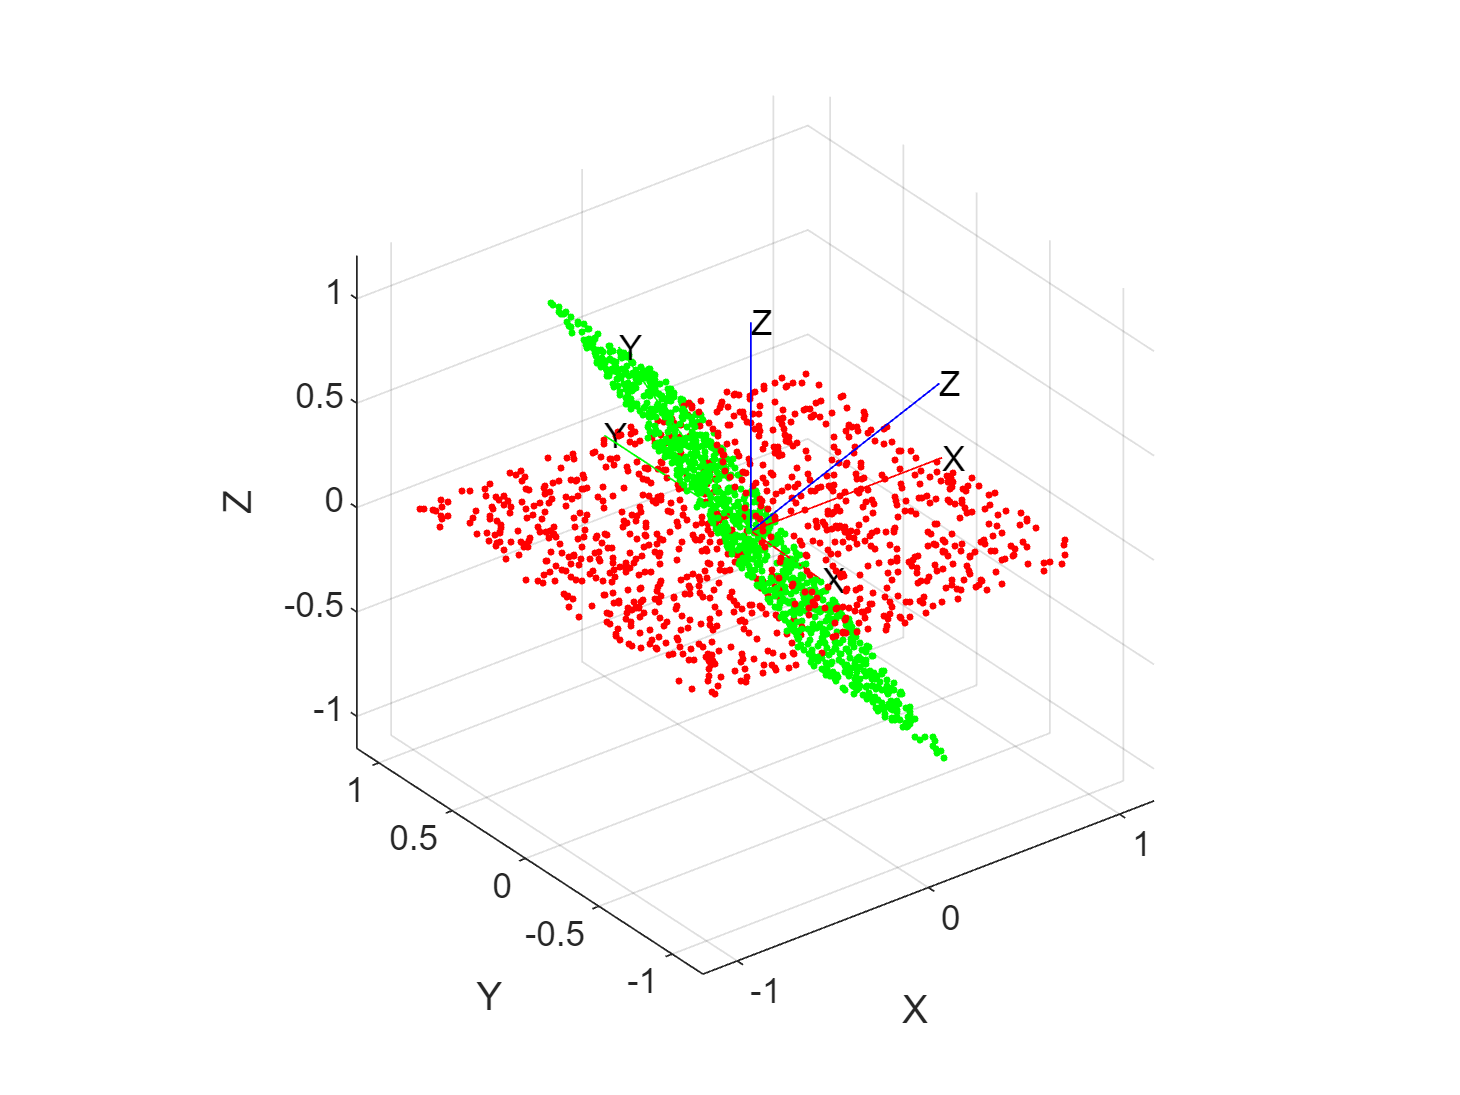


puntosR= (rotm(Rot)*puntos')';
figure
hold on
plotTransforms(se3(),'AxisLabels','on','FrameAxisLabels','on')
plot3(puntos(:,1), puntos(:,2), puntos(:,3), '.r')

% Dibuja el eje
plotTransforms(se3(Rot),'AxisLabels','on','FrameAxisLabels','on')
plot3(puntosR(:,1), puntosR(:,2), puntosR(:,3), '.g')

## Rotaciones sobre el eje base, no eje anterior

- Cuando las rotaciones se realizan sobre el eje base, no sobre el anterior obtenido, el resultado es el producto a la izquierda, $R_{zyx}^{base}=R_x*R_y*R_z$.

- El resultado de giros respecto de la base y giros respecto del eje anterior es muy diferente. 

- Se suele usar para posicionar figuras dentro del espacio

- La rotación $ZXY$respecto de la base es la $XYZ$, $R_{zyx}^{base}=R_{xyz}$, respecto del eje anterior y al revés.

#### Ejemplo, objeto so3

Rzyx= so3(Rz(30*deg)*Ry(40*deg)*Rx(50*deg))

Rzyx = so3
    0.6634    0.1050    0.7408
    0.3830    0.8029   -0.4568
   -0.6428    0.5868    0.4924


eulzyx= eul(Rzyx,'ZYX')/deg % en grados

eulzyx =    30.0000   40.0000   50.0000


RzyxB= so3(Rx(50*deg)*Ry(40*deg)*Rz(30*deg))

RzyxB = so3
    0.6634   -0.3830    0.6428
    0.7478    0.3105   -0.5868
    0.0252    0.8700    0.4924


eulzyxB= eul(RzyxB,'ZYX')/deg % en grados

eulzyxB =    48.4231   -1.4441   60.4910


- En el caso particular de $R_{zyx}$ y $R_{zyx}^{base}$ hay una relación, pero no es general

eulzyx= -eul(inv(RzyxB),'ZYX')/deg

eulzyx =    30.0000   40.0000   50.0000


## Row (alabeo) ($\phi_r$) Pitch (cabeceo) ($\phi_p$) y Yaw (guiñada) ($\phi_y$).

- Roll (alabeo, $\phi_r$, normalmente se asigna al eje $z$ y a veces a $x$).

- Pitch (cabeceo, $\phi_p$, normalmente se asigna al eje $y$)

- Yaw (guiñada, $\phi_y$, normalmente se asigna al eje $x$ y a veces a $z$)

Si los giros se realizan respecto el eje anterior,


$$R(\phi_{rpy})= R_z(\phi_r)*R_y(\phi_p)*R_x(\phi_y)$$


## 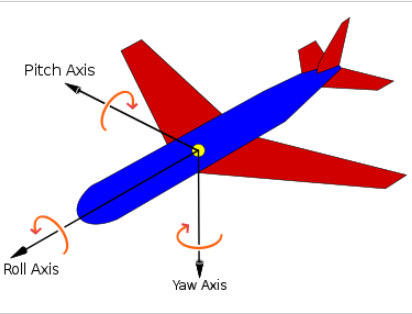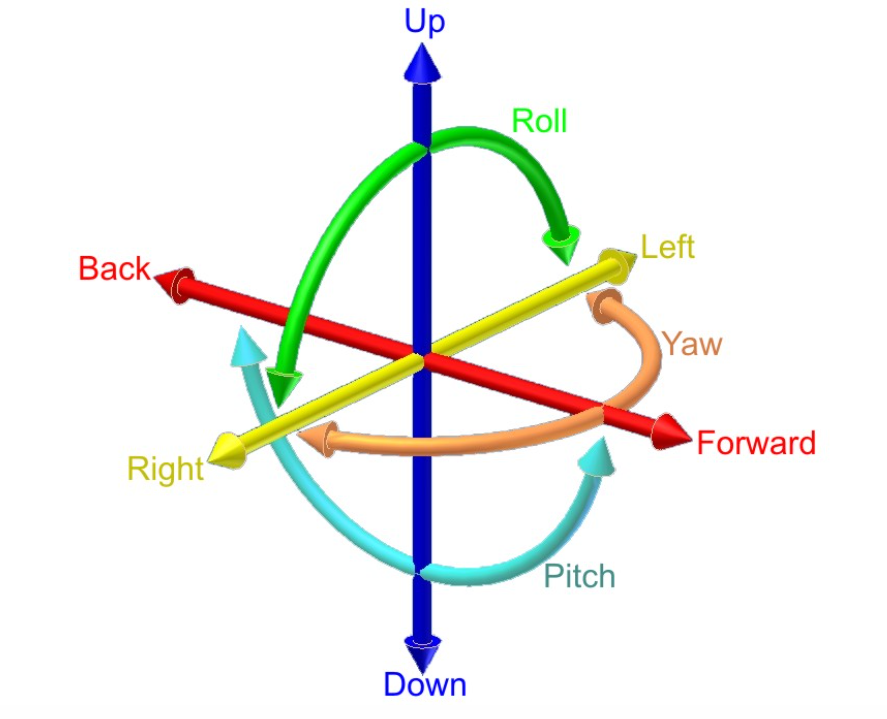

## Ángulo-vector

- Se define un vector de giro $v$ (unitario) y un ángulo $\theta$ (4 componentes, 3 grados de libertad).

- El vector de giro $\nu=[x,y,z]$ sale de la proyección del vector sobre los ejes $x$, $y$, y $z$. Dicho vector se normaliza.

- El ángulo $\theta$ es el ángulo en radianes de giro del vector

#### Ejemplo: objeto so3

% Giro en el eje x
Rot= so3([1,0,0,30*deg],'axang')
eul(Rot)/deg

ans =      0     0   180


## Cuaternios:

- A partir de $v$ y $\theta$ del ángulo vector, se define un vector de 4 componentes $[cos(\theta/2),v*sin(\theta/2)]$. 

- Se trabaja con cuaternios unitarios (4 componentes, 3 grados de libertad), cuya norma es $1$.

- Álgebra de cuaternios: Los cuaternios tienen propiedades algebraicas, suma, resta, producto e inversa. Por ello, pueden ser usados de forma análoga a las matrices rotacionales.

- Cuaternios importantes: La relación entre cuaternios $[q_1,q_2,q_3,q_4]$ y rotaciones básicas $[R_x,R_y,R_z]$ (en grados) es la siguiente: $[1,0,0,0]\rightarrow [0,0,0]$, $[0,1,0,0]\rightarrow [180,0,0]$, $[0,0,1,0]\rightarrow [0,180,0]$ y $[0,0,0,1]\rightarrow [0,0,180]$

#### Ejemplo con objeto so3

% Giro en x de 180
Rot= so3([0,1,0,0],'quat');
eul(Rot)/deg

## Matriz homogénea: 

- Incluye en una matriz (4 x 4) el vector desplazamiento y la matriz rotación

                                         
$$^BT_A= \left[  \begin{array}{cc}  ^BR_A & t \\ 0 & 1\end{array}  \right]$$
     

             donde $t=[x,y,z]'$ es la traslación y $^BR_A$ la rotación entre el sistema B respecto del A

- Composición de sistema: Si $^BT_A$ es la matriz homogénea entre B y A, y $^CT_B$ entre C y B, la matriz homogénea entre C y A será, $^CT_A=^CT_B*^BT_A$.

-  Paso de un punto de eje a otro: Un punto $^Ap$ homogéneo $p=[x,y,z,1]'$ visto desde B es $^Bp= ^BT_A*^Ap$ 

#### Objeto se3

Hf= @(R,t) [R,t(:); zeros(1,3),1];


H1 =     0.8138   -0.4410    0.3785    0.1000
    0.4698    0.8826    0.0180    0.2000
   -0.3420    0.1632    0.9254    0.3000
         0         0         0    1.0000


t= [100,200,300]*1e-3;
H1= Hf(Rz(30*deg)*Ry(20*deg)*Rx(10*deg), t)

H2 = se3
    0.8138   -0.4410    0.3785    0.1000
    0.4698    0.8826    0.0180    0.2000
   -0.3420    0.1632    0.9254    0.3000
         0         0         0    1.0000


% Formato de entrada para objeto se3 'ZYX' por defecto
H2= se3([30,20,10]*deg,'eul','ZYX',t)

#### Movimiento de una nube de puntos

- Los puntos de un eje pasa a otro dado, traslación y rotación

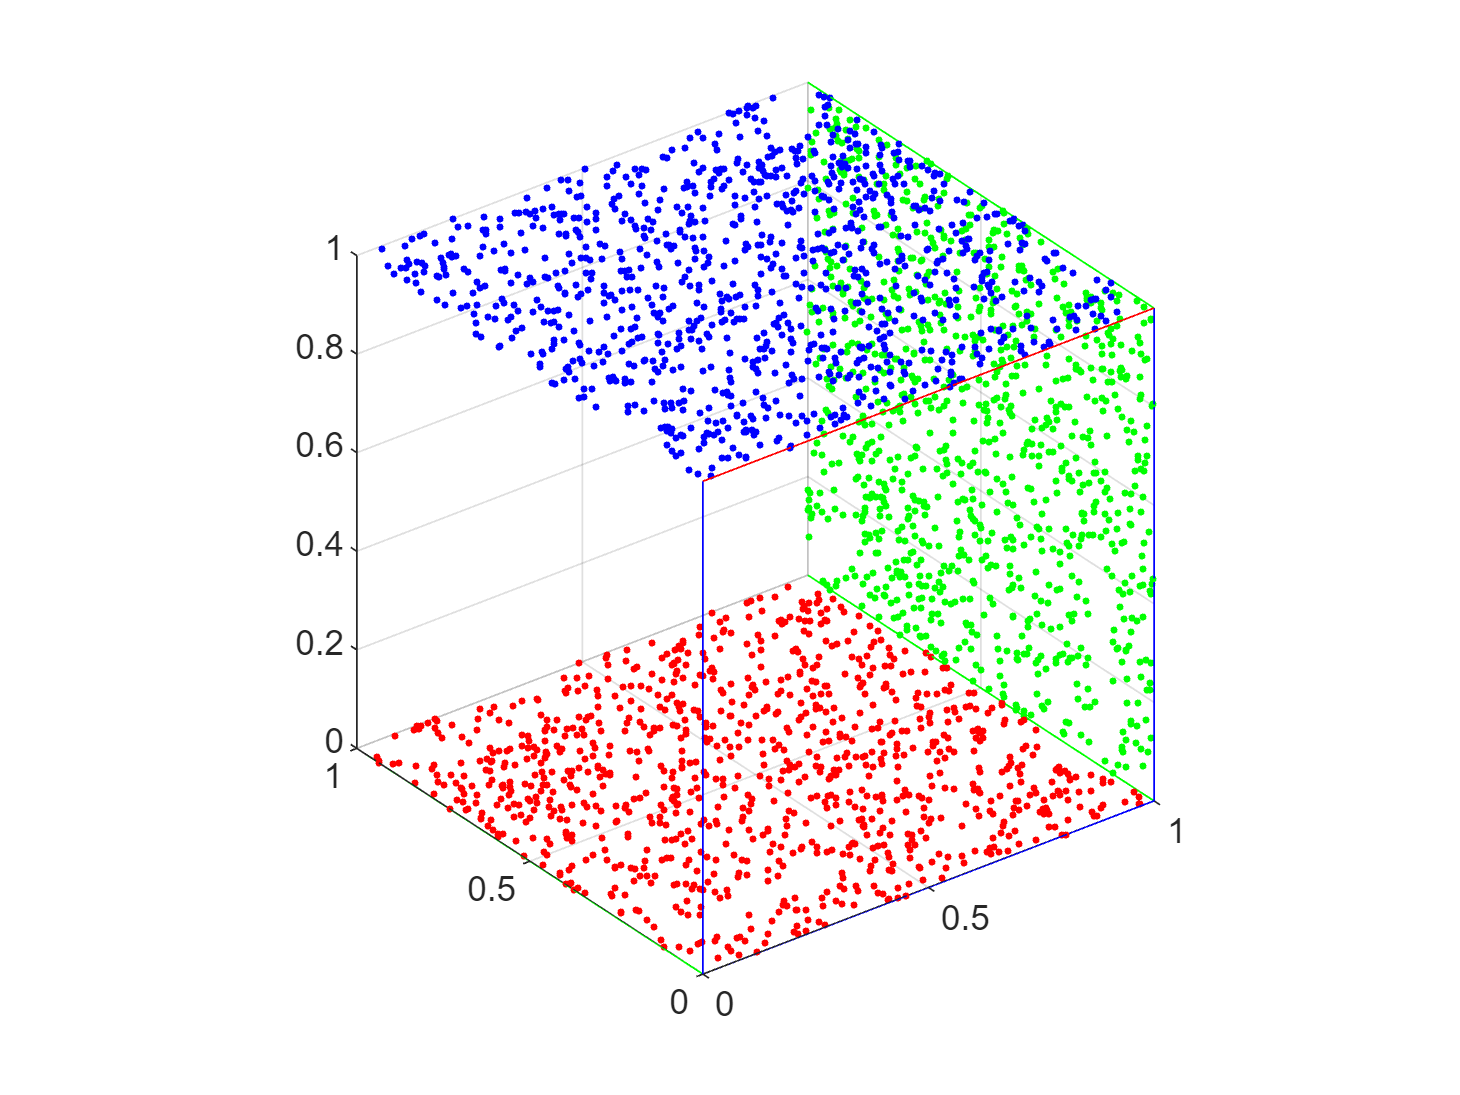

% Puntos aleatorios en la base
nPts= 1e3;
x= rand(nPts,1);
y= rand(nPts,1);
z= zeros(nPts,1);

figure

% Puntos homogéneos
puntos= [x,y,z,ones(nPts,1)];

H0= se3;

figure
hold on
plotTransforms(H0);
plot3(puntos(:,1), puntos(:,2), puntos(:,3),'.r')

% Movimiento en x, giro en y (-90)
H1= se3([0,-90*deg,0],'eul',[1,0,0]);

puntos1= (tform(H1)*puntos')';
plotTransforms(H1);
plot3(puntos1(:,1),puntos1(:,2),puntos1(:,3),'.g')
puntos2= (tform(H1*H1)*puntos')';
plotTransforms(H1*H1);
plot3(puntos2(:,1),puntos2(:,2),puntos2(:,3),'.b')

## Función $[H,pose]= Prod(obj1, obj2)$

- La librería SimRobot va a trabajar con dos modelos de ejes, la matriz homogénea y el vector $pose=[[x,y,z]m,[R_z,R_y,R_x]rad]$.

- La función $Prod()$ está definida para multiplicar distintos tipos de datos, analizando la entrada y convirtiendo éstas de forma apropiada.

- Si solo tiene una entrada, puede ser útil para conversión de tipos de datos.

- La salida es la matriz homogénea del producto $H$ y su valor vectorial equivalente $pose$.

#### Ejemplos


deg= pi/180;
pose1= [[100,100,200]*1e-3,[0,0,90]*deg];
pose2= [[0,0,0]*1e-3,[90,0,0]*deg];

H1= Prod(pose1); % Convierte pose en H

[H3,pose3]= Prod(H1,pose2) % Multiplica tipos diferentes.

H3 =     0.0000   -1.0000         0    0.1000
    0.0000    0.0000   -1.0000    0.1000
    1.0000    0.0000    0.0000    0.2000
         0         0         0    1.0000


pose3 =     0.1000    0.1000    0.2000         0   -1.5708    1.5708


## Generar un eje a partir de 3 puntos 

- Por optimización local se genera un eje a partir de tres puntos dados.

- La función $Prod()$ devuelve el eje asociado a 3 puntos cuando el número de entradas es 3.

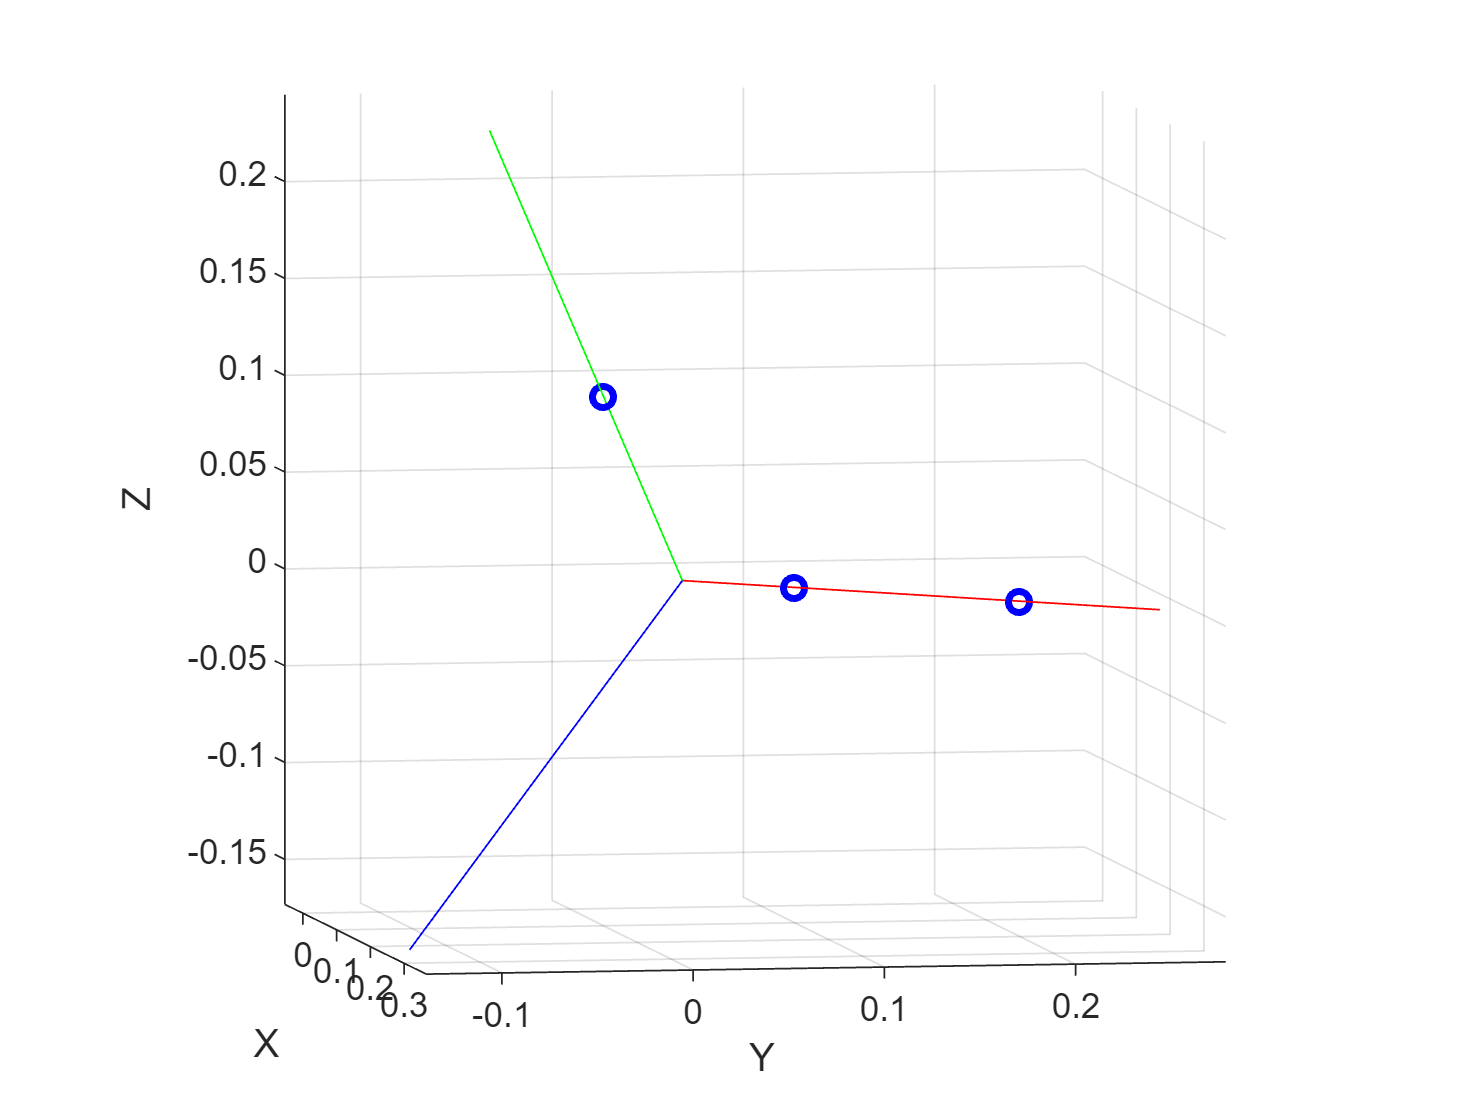

%% Generar un eje a partir de 3 puntos 
% p1 y p2 en el eje x p3 en el eje y
p1= [.1,.1,0]; p2= [.2,.2,0]; p3= [.1,0,0.1];
pts= [p1; p2; p3];
% Generación de los ejes
figure 
H= se3(Prod(p1, p2, p3));
plotTransforms(H,'AxisLabels','on','FrameSize',0.3)
hold on
plot3(pts(:,1), pts(:,2), pts(:,3), ...
                 'bo', 'LineWidth', 2)
view(80,5)

## Trayectorias

- Las trayectorias es la obtención de una serie de ejes entre dos dados con diferentes criterios.

- Interpolar entre matrices homogéneas y/o matrices de rotación.

- Se puede interpolar con mayores criterios de velocidad y aceleración.

- Se puede interpolar entre más de dos puntos

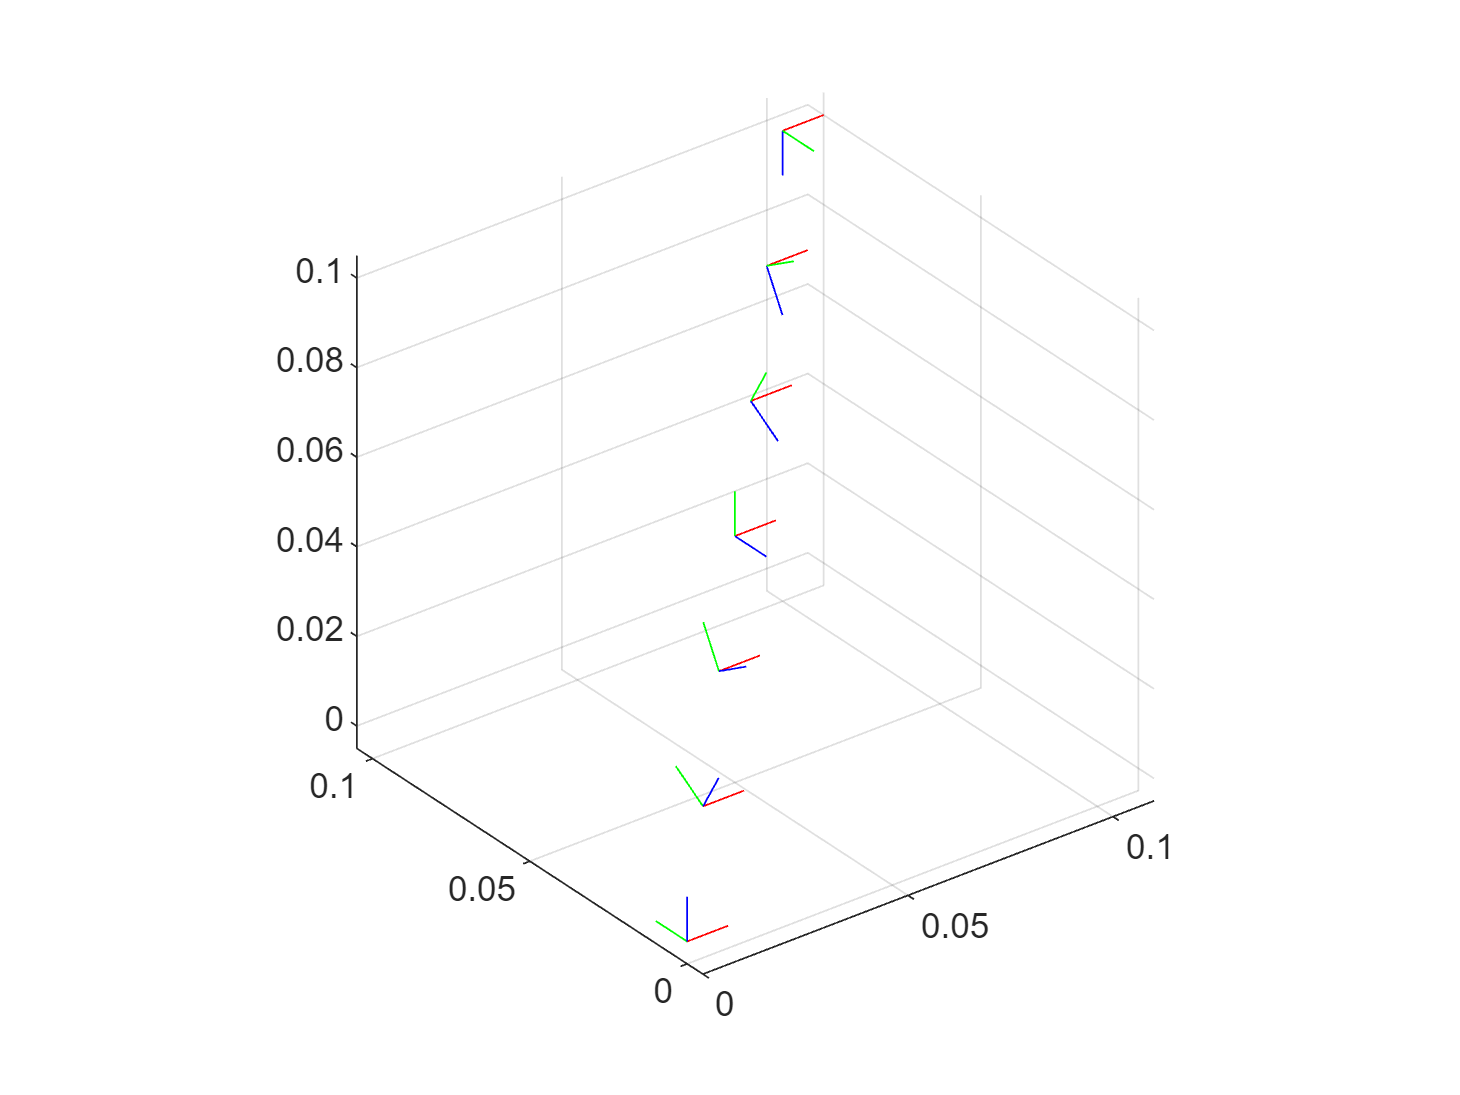

deg= pi/180;
nPts= 7;

H1= se3(Prod([[0,0,0]*1e-3, [0,0,0]*deg]));
H2= se3(Prod([[100,100,100]*1e-3, [0,0,180]*deg]));

H= interp(H1,H2,nPts);
%H= transformtraj(H1, H2, [0,1], 0:0.1:1);
figure
hold on
for i= 1:nPts
   plotTransforms(H(i),'FrameSize',10*1e-3);
end

#### Posición y Orientación en los lenguajes de programación: 

- ABB: RAPID (mm y cuaternios) RobotStudio (mm y $R_{xyz}^{base}$ grados) 

- UR: PolyScope (mm y $R_{xyz}$ grados) lenguaje Script (m y $R_{xyz}$ radianes)

- ROS: Algunos robots (por ejemplo, robot Niryo) usan Roll-Pitch-Yaw, para mover el TCP del robot, donde Roll es $x$, Pich es $y$ Yaw es $z$.

## Transformaciones homogéneas

## Objetos para rotaciones y transformaciones homogéneas


% se2	SE(2) homogeneous transformation
% se3	SE(3) homogeneous transformation
% so2	SO(2) rotation
% so3	SO(3) rotation
% plotTransforms	Plot 3-D transforms from translations and rotations
% transformMotion	Compute motion quantities between two relatively fixed frames


% Consructor
    % transformation = se3
    % transformation = se3(rotation)
    % transformation = se3(rotation,translation)
    % transformation = se3(transformation)
    % transformation = se3(euler,"eul")
    % transformation = se3(euler,"eul",sequence)
    % transformation = se3(quat,"quat")
    % transformation = se3(quaternion)
    % transformation = se3(axang,"axang")
    % transformation = se3(angle,axis)
    % transformation = se3(___,translation,"trvec")
    % transformation = se3(translation,"trvec")
    % transformation = se3(pose,"xyzquat")

 % Object Functions
 %      xyzquat   - Convert transformation or rotation to compact 3-D pose representation
 %      quat      - Convert transformation or rotation to numeric quaternion
 %      eul       - Convert transformation or rotation into Euler angles
 %      axang     - Convert transformation or rotation into axis-angle rotations
 %      trvec     - Extract translation vector
 %      transform - Apply rigid body transformation to points
 %      tform     - Extract homogeneous transformation
 %      rotm      - Extract rotation matrix
 %      normalize - Normalize transformation or rotation matrix
 %      interp    - Interpolate between transformations
 %      dist      - Calculate distance between transformations
 %      times     - Element-wise transformation or rotation multiplication
 %      rdivide   - Element-wise transformation or rotation right division
 %      mtimes    - Transformation or rotation multiplication
 %      mrdivide  - Transformation or rotation right division


## Visualization


%    plotTransforms	Plot 3-D transforms from translations and rotations
%    poseplot	3-D pose plot

%    transformMotion	Compute motion quantities between two relatively fixed frames


## Axis-Angles


% axang2quat	Convert axis-angle rotation to quaternion
% axang2rotm	Convert axis-angle rotation to rotation matrix
% axang2tform	Convert axis-angle rotation to homogeneous transformation


## Euler Angles

% eul2quat	Convert Euler angles to quaternion
% eul2rotm	Convert Euler angles to rotation matrix
% eul2tform	Convert Euler angles to homogeneous transformation

## Quaternions


% quaternion	Create a quaternion array
% quat2axang	Convert quaternion to axis-angle rotation
% quat2eul	Convert quaternion to Euler angles
% quat2rotm	Convert quaternion to rotation matrix
% quat2tform	Convert quaternion to homogeneous transformation


## Rotation Matrices


% SO3	SO(3) rotation
% rotm2axang	Convert rotation matrix to axis-angle rotation
% rotm2eul	Convert rotation matrix to Euler angles
% rotm2quat	Convert rotation matrix to quaternion
% rotm2tform	Convert rotation matrix to homogeneous transformation


## Homogeneous Transformations


% tform2axang	Convert homogeneous transformation to axis-angle rotation
% tform2eul	Extract Euler angles from homogeneous transformation
% tform2quat	Extract quaternion from homogeneous transformation
% tform2rotm	Extract rotation matrix from homogeneous transformation
% tform2trvec	Extract translation vector from homogeneous transformation

## Latitude, Longitude, NED, and ENU


% enu2lla	Transform local east-north-up coordinates to geodetic coordinates
% lla2enu	Transform geodetic coordinates to local east-north-up coordinates
% lla2ned	Transform geodetic coordinates to local north-east-down coordinates
% ned2lla	Transform local north-east-down coordinates to geodetic coordinates


## Coordinate Conversions


% angdiff	Difference between two angles
% cart2hom	Convert Cartesian coordinates to homogeneous coordinates
% hom2cart	Convert homogeneous coordinates to Cartesian coordinates
% trvec2tform	Convert translation vector to homogeneous transformation


## Trajectory Generation

% Trajectory Generation
%     cubicpolytraj     - Generate third-order polynomial trajectories through multiple waypoints
%     quinticpolytraj   - Generate fifth-order polynomial trajectories through multiple waypoints
%     bsplinepolytraj   - Generate multi-axis trajectories through control points using B-splines
%     transformtraj     - Generate trajectory between two homogeneous transforms
%     trapveltraj       - Generate piecewise polynomials through multiple waypoints using trapezoidal velocity profiles
%     rottraj           - Generate trajectory between two orientations
%     minjerkpolytraj   - Generate minimum jerk trajectories through multiple waypoints
%     minsnappolytraj   - Generate minimum snap trajectories through multiple waypoints
%     contopptraj       - Create constrained time-optimal path parametrized trajectory
 

% waypointTrajectory	Waypoint trajectory generator
% kinematicTrajectory	Rate-driven trajectory generator